# **Tutorial 2:** a spacecraft with 2 symmetrical rotating solar arrays ( $\approx 1\;mn$ run).

*by D. Alazard and F. Sanfedino - ISAE-SUPAERO*

## 1. Description

The objective is to compute the $6\times 6$ inverse dynamic model $[\mathbf D_B^{\mathcal{SC}}]_{\mathcal R_b}^{-1}(\mathrm s, \theta)$ of the spacecraft $\mathcal{SC}$ depicted in the following Figure.

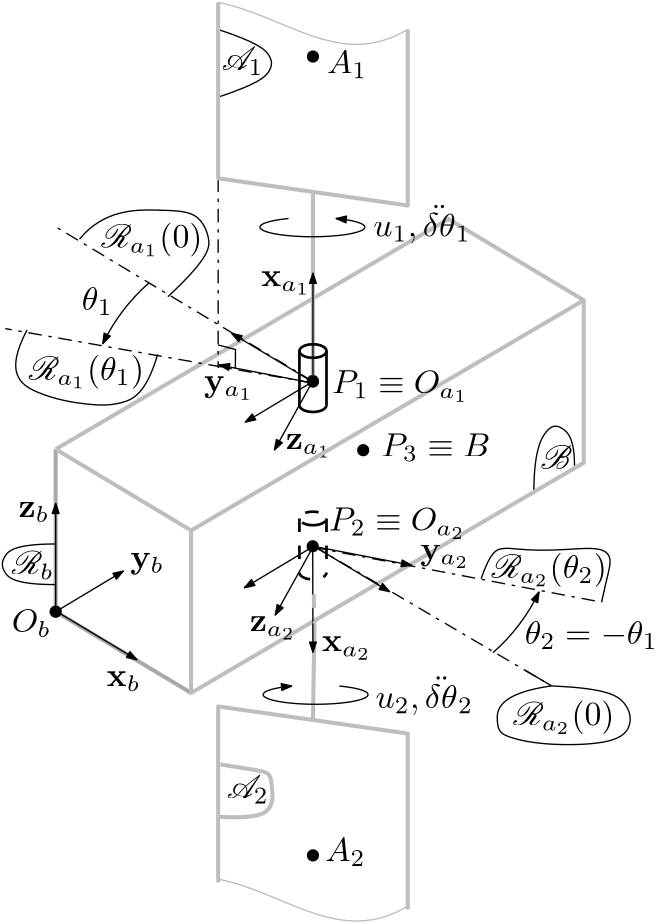

The spacecraft $\mathcal{SC}$ is composed of:

- the main body $\mathcal B$ with its center of gravity $B$, its reference point $O_b$ and its body frame $\mathcal R_b$,

- 2 symmetrical flexible solar arrays $\mathcal A_1$ and $\mathcal A_2$ connected to $\mathcal B$ at the points $P_1$ and $P_2$ respectively, through a revolute joint. $A_i$, $O_{a_i$ and $\mathcal R_{a_i}$ are the centre of gravity, the reference point and the body frame of $\mathcal A_i$ ($i=1,\,2$).

The angular configurations of the 2 solar panels are symmetrical: $\theta_1=\theta$ and $\theta_2=-\theta$. In the Figure, $\mathcal R_{a_i}(0)$ and $\mathcal R_{a_i}(\theta_i)$ represent $2$ geometric configurations of $\mathcal R_{a_i}$ for the nominal configuration ( $\theta_i=0$) and for a given angle $\theta_i$.

$[\mathbf D_B^{\mathcal{SC}}]_{\mathcal R_b}^{-1}(\mathrm s, \theta)$ is the model of the spacecraft at the centre of gravity $B$ of the main body $\mathcal B$and projected in the main body frame axes $\mathcal R_b$ for a given angular configuration $\theta$, that is the $18\times 6$ transfer between:

- the resultant external wrench $[\mathbf W_{ext/\mathcal B,B}]_{\mathcal R_b}$ (6 components: 3 forces and 3 torques) applied to $\mathcal B$ at the point $B$,

- the motion vector at point $B$ $[\delta\mathbf m^{\mathcal{SC}}_B]_{\mathcal R_b}$(18 components).

Each revolute joint $i$ adds in the model a SISO (Single-Input Single Ouput) channel between:

- the torque $u_i$ applied by $\mathcal B$ to $\mathcal A_i$ around $\mathbf x_{a_i}$inside the revolute joint,

- the relative acceleration $\ddot{\delta\theta}_i$ of $\mathcal A_i$ w.r.t. $\mathcal B$ around $\mathbf x_{a_i}$.

To hold the angular configuration of $\mathcal A_i$ w.r.t. $\mathcal B$ at the value $\theta_i$, the driving mechanism inside the revolute joint is modeled as a local  stiffness $k_i$ ($Nm/rad$), a viscous friction $f_i$ ($Nms/rad$) and an internal disturbing torque $p_i$ ($Nm$):

$u_i=-k_i \delta\theta_i-f_i\dot{\delta\theta}_i+p_i$.

## 2. Required data.

### Data relative to the main body $\mathcal B$:

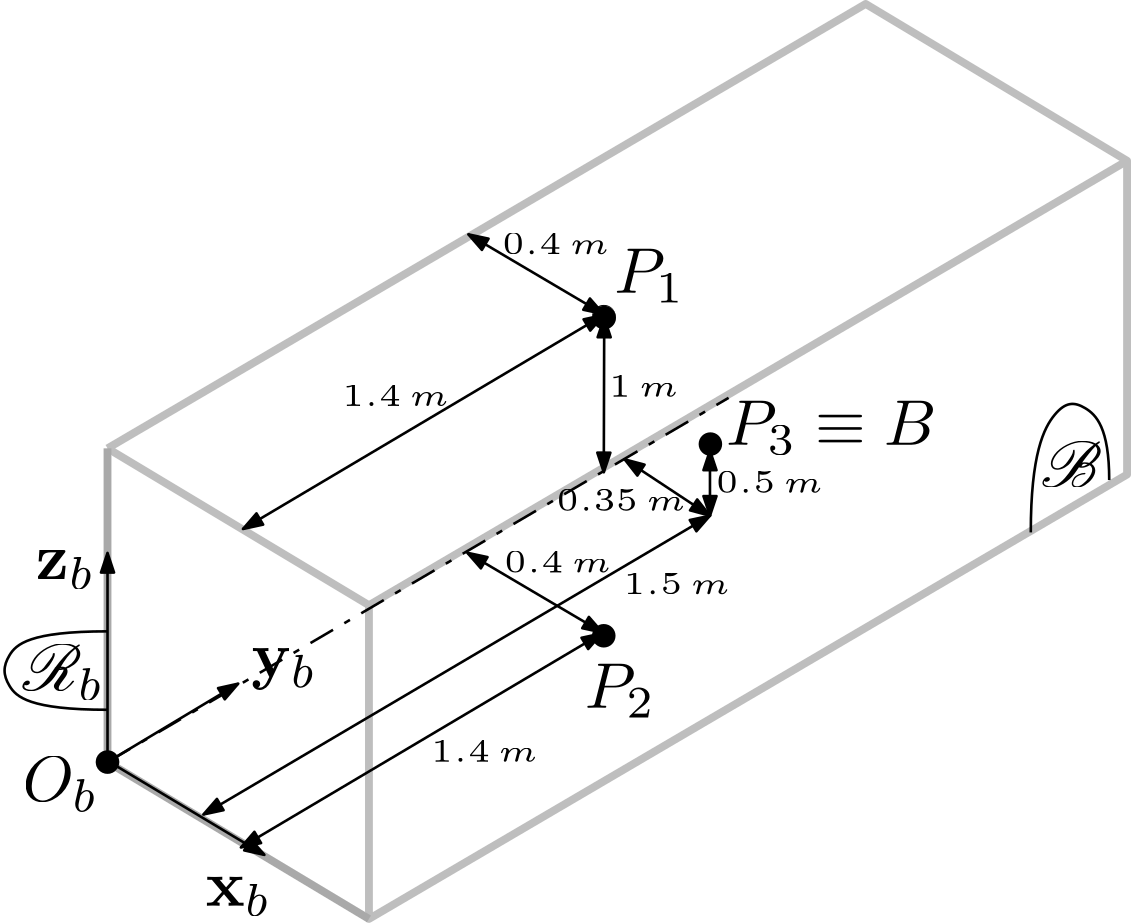

All the data are expressed in the body frame $\mathcal{R}_b$:

- geometry (in $m$): $[\vec{OP_1}]_{\mathcal R_b}=[0.4\quad 1.4\quad 1]^T$, $[\vec{OP_2}]_{\mathcal R_b}=[0.4\quad 1.4\quad 0]^T$, $[\vec{OB}]_{\mathcal R_b}=[0.35\quad 1.5\quad 0.5]^T$,

- mass: $m^{\mathcal B}=1000\,(Kg)$,

- 3x3 inertia tensor at $B$: $[\mathbf J_B^{\mathcal B}]_{\mathcal R_b}=\left[\begin{array}{ccc} 75 & 1 & 2 \\ 1 & 40 & -1\\ 2 & -1 & 80\end{array}\right]$ ($Kg\,m^2$).

This body can be simply modeled with the block `multi port rigid free body` of the sub-library `6 dof bodies` of the `SDTlib`. The dialog box allows to choose 3 ports (i.e. 3 points, the last port `P3` corresponds to the center of mass $B$) and to fill all the data:

 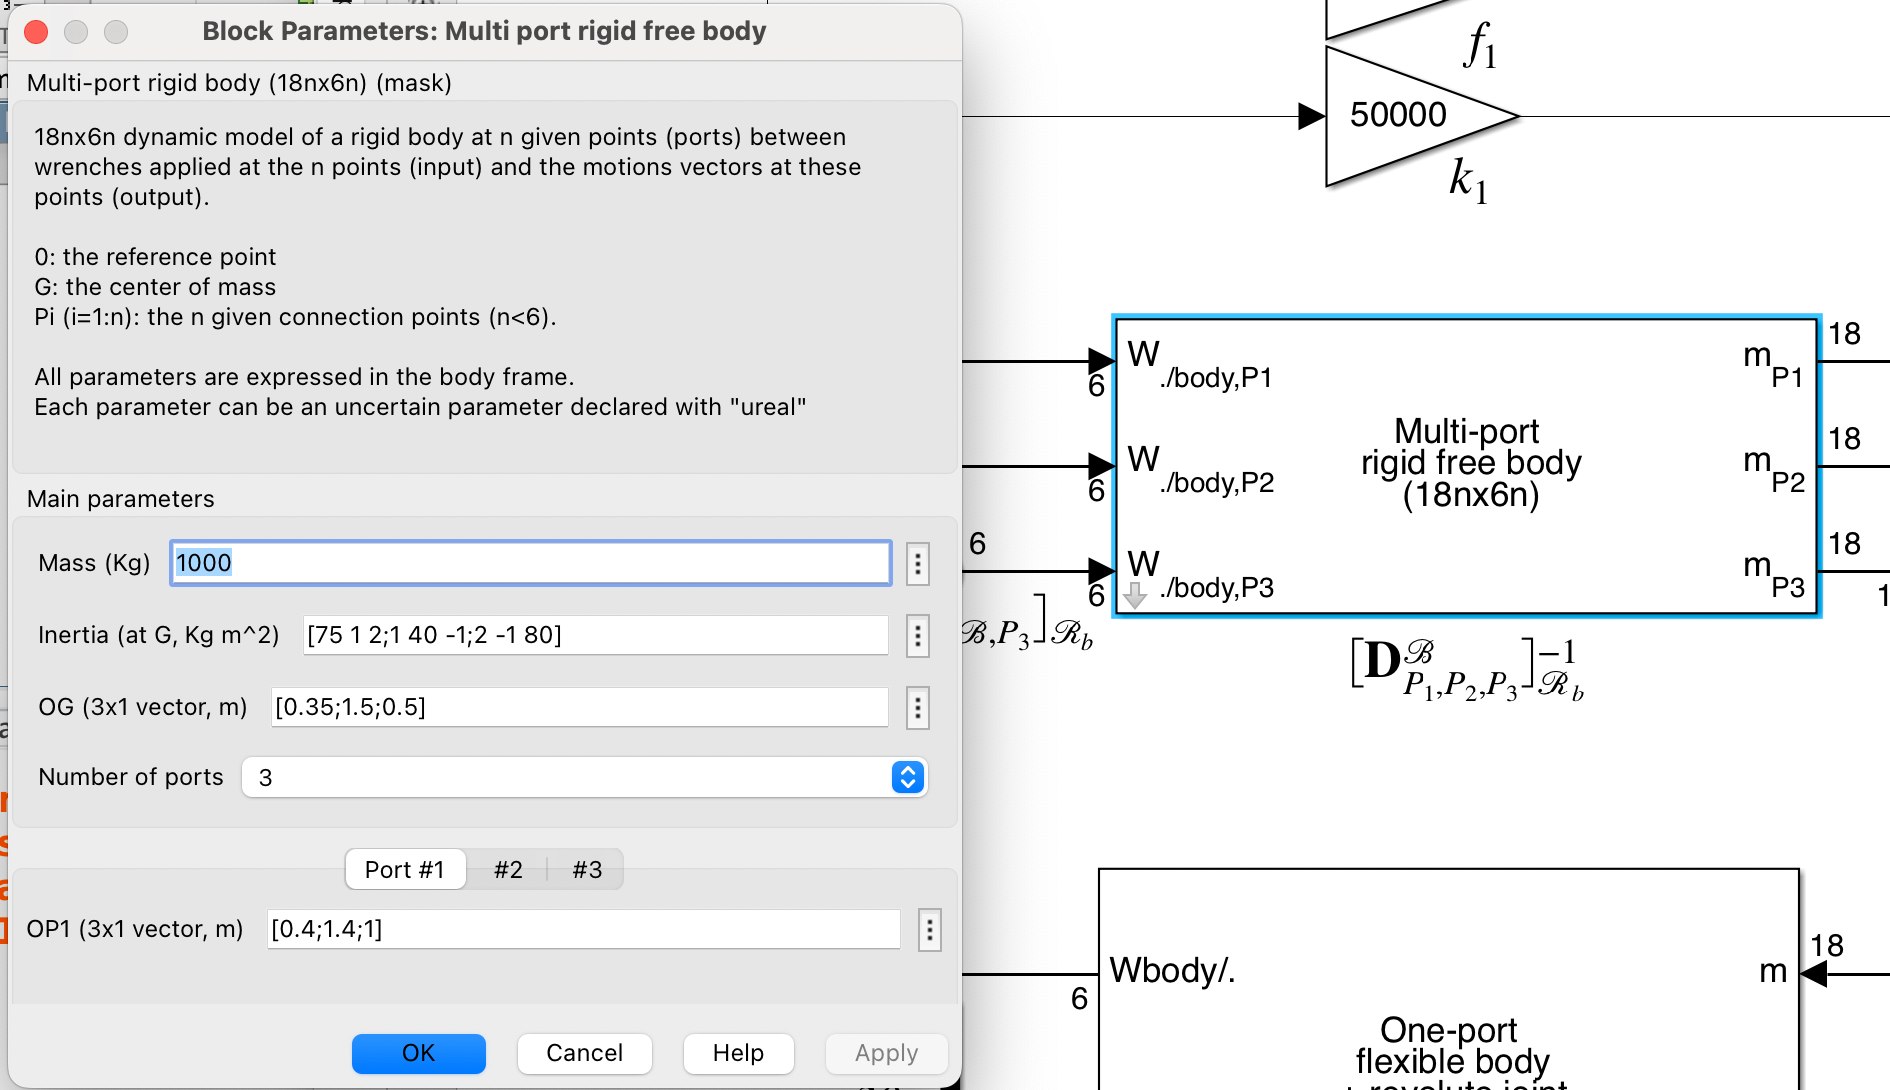

The inline `help `in the dialog box opens the web browser and describes the mathematical model $[\mathbf D^{\mathcal B}_{P_1,P_2,P_3}]^{-1}$ of this block (internet connection required).  This help is also avalaible by:

web Docmultiportrigidbase.html -new

### Direction Cosine Matrix (DCM):

$\mathbf P_{a_1(0)/b}=\left[\begin{array}{ccc}0 & -1 & 0\\0 & 0 & -1\\1 & 0 & 0\end{array}\right]$ is the DCM

- from the body $\mathcal A_1$ frame: $\mathcal R_{a_1}(0)$in the nominal configuration ($\theta=0$) 

- to the body $\mathcal B$ frame: $\mathcal R_b$.

(That is the matrix of the coordinates of $\mathbf x_{a_1}(0)$, $\mathbf y_{a_1}(0)$ and $\mathbf z_{a_1}(0)$expressed in $\mathcal R_b$.)

In the same way: $\mathbf P_{a_2(0)/b}=\left[\begin{array}{ccc}0 & 1 & 0\\0 & 0 & -1\\-1 & 0 & 0\end{array}\right]$.

These DCM can be modeled with the block `6x6 DCM` and` 18x18 DCM` of the sub-library `3/6/18 DCM` of the `SDTlib`:

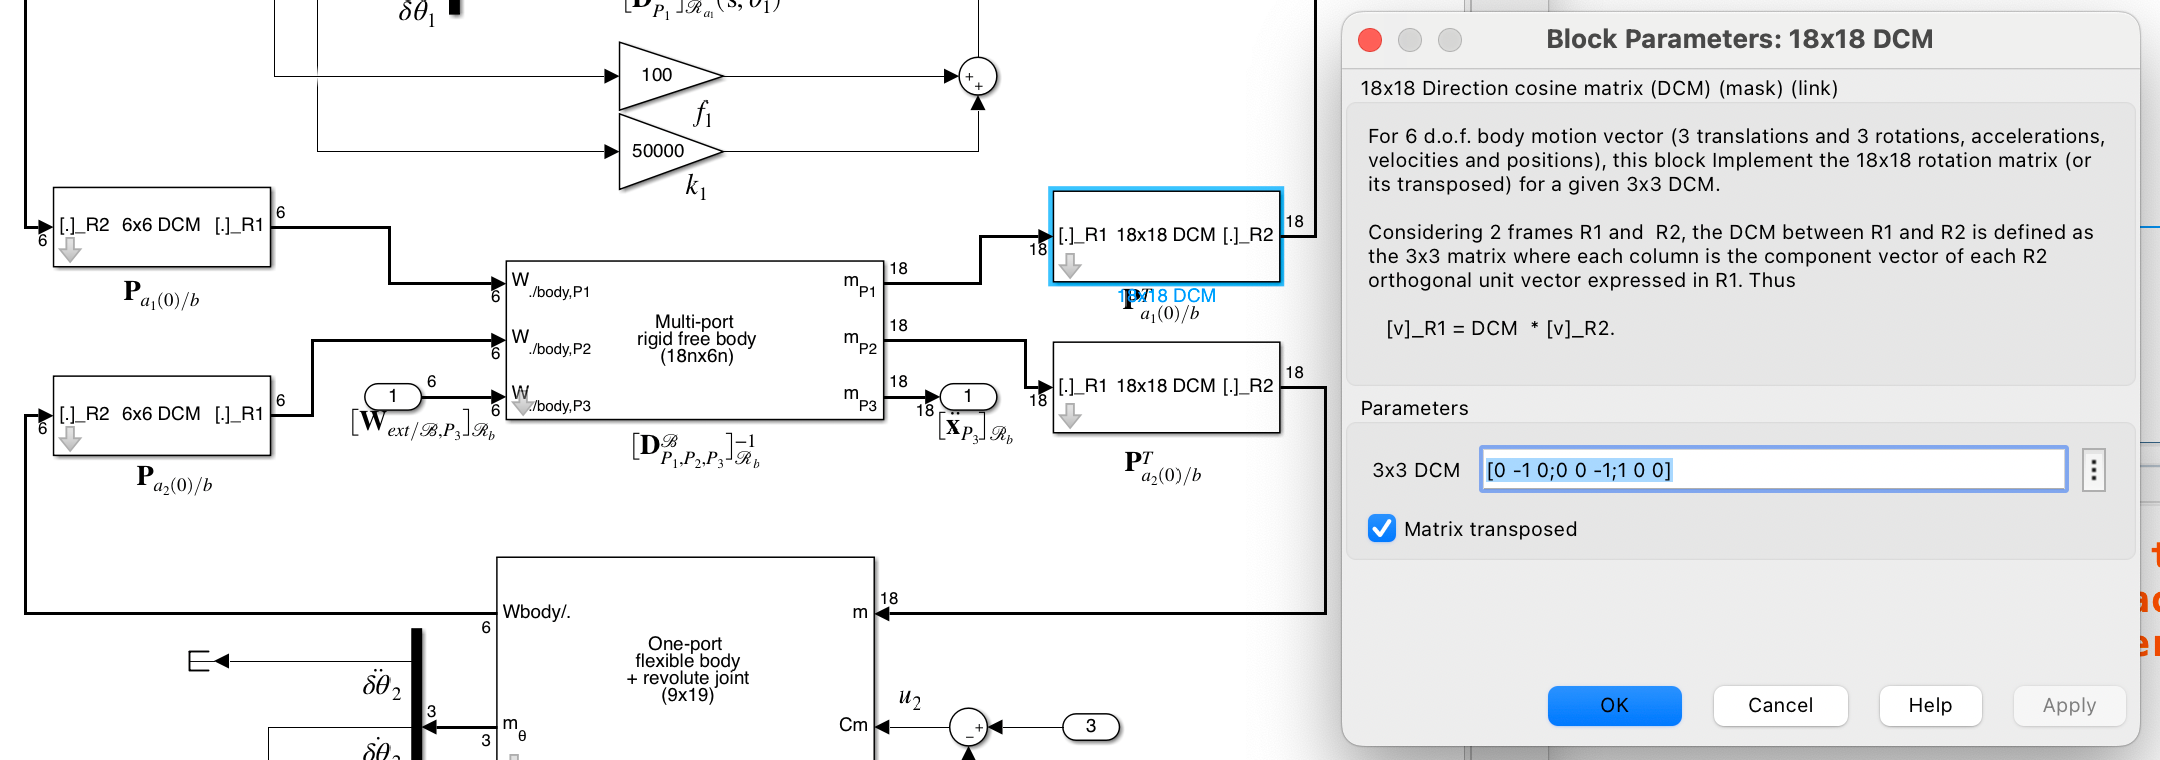

### Data relative to the solar array $\mathcal A_1$:

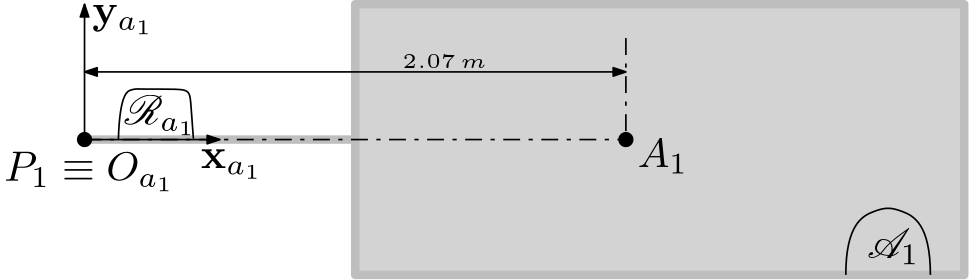

All the data are expressed in the body frame $\mathcal{R}_{a_1}$:

- geometry (in $m$): $[\vec{O_{a_1}A_1}]_{\mathcal R_{a_i}}=[2.07\quad 0\quad 0]^T$, $[\vec{O_{a_1}P_1}]_{\mathcal R_{a_i}}=[0\quad 0\quad 0]^T$

- mass: $m^{\mathcal A_1}=43\,(Kg)$,

- 3x3 inertia tensor at $A_1$: $[\mathbf J_{A_1}^{\mathcal A_1}]_{\mathcal R_{a_1}}=\left[\begin{array}{ccc} 17 & 0 & 0 \\ 0 & 62 & 0\\ 0 & 0 & 79\end{array}\right]$ ($Kg\,m^2$),

- the frequencie $\omega_j$ and  the$1\times 6$ modal participation factor vector $\mathbf l_{j,P_1$ at the connection point $P_1$ of the $j$-th solar array flexible mode.

- the common damping ratio for the flexible modes $\xi=0.005$.

3 flexible modes are considered for $\mathcal A_1$ :


$$\begin{array}{l | l | l} j \quad  & \omega_j\,(rad/s)\quad& [\mathbf l_{j,P_1}]_{\mathcal R_{a_1}}=[T_x,\;T_y,\;T_z,\;R_x,\;R_y,\;R_z ]\;(\sqrt{Kg}, m\sqrt{Kg}) \\ \hline \\ 1 & 5.6 & [0\quad0\quad-5.12\quad0\quad12.5\quad 0] \\ 2 & 19.3 & [0\quad 0 \quad 0\quad -3.84 \quad 0 \quad 0]\\ 3 & 35.4& [0\quad 0\quad -2.97\quad 0\quad 2.51 \quad 0] \\ \hline\end{array}$$


The revolute joint along $\mathbf x_{a_1}$-axis at the connection point $P_1$ can be taken into account using the block `1 port flexible body + revolute joint` of the sub-library `predefined subsystems` of the` SDTlib`. 

The revolute joint is characterized by:

- the revolute axis direction : $[\mathbf r_{a_1}]_{\mathcal R_{a_1}}=[1\quad 0\quad 0]^T$,

- its angular configuration $\theta$ which can be declared as a varying parameter:  `ureal('Theta',0,'Range',[-pi,pi]) `to have a model valid for a whole turn of the solar array.

The DCM $\mathbf P_{a_1(\theta)/a_1(0)}=\left[\begin{array}{ccc}1 & 0 & 0\\0 & \cos\theta & -sin\theta\\0 & \sin\theta & \cos\theta \end{array}\right]$ from the frame $\mathcal R_{a_1}(\theta)$ to the frame $\mathcal R_{a_1}(0)$ is included in the block and is parameterized according to $\sigma_4=\tan\frac{\theta}{4}$ to be expressed under the LFT (Linear Fractional Transformation) formalism.

The dialog box of the block `1 port flexible body + revolute joint` allows to fill all the data:

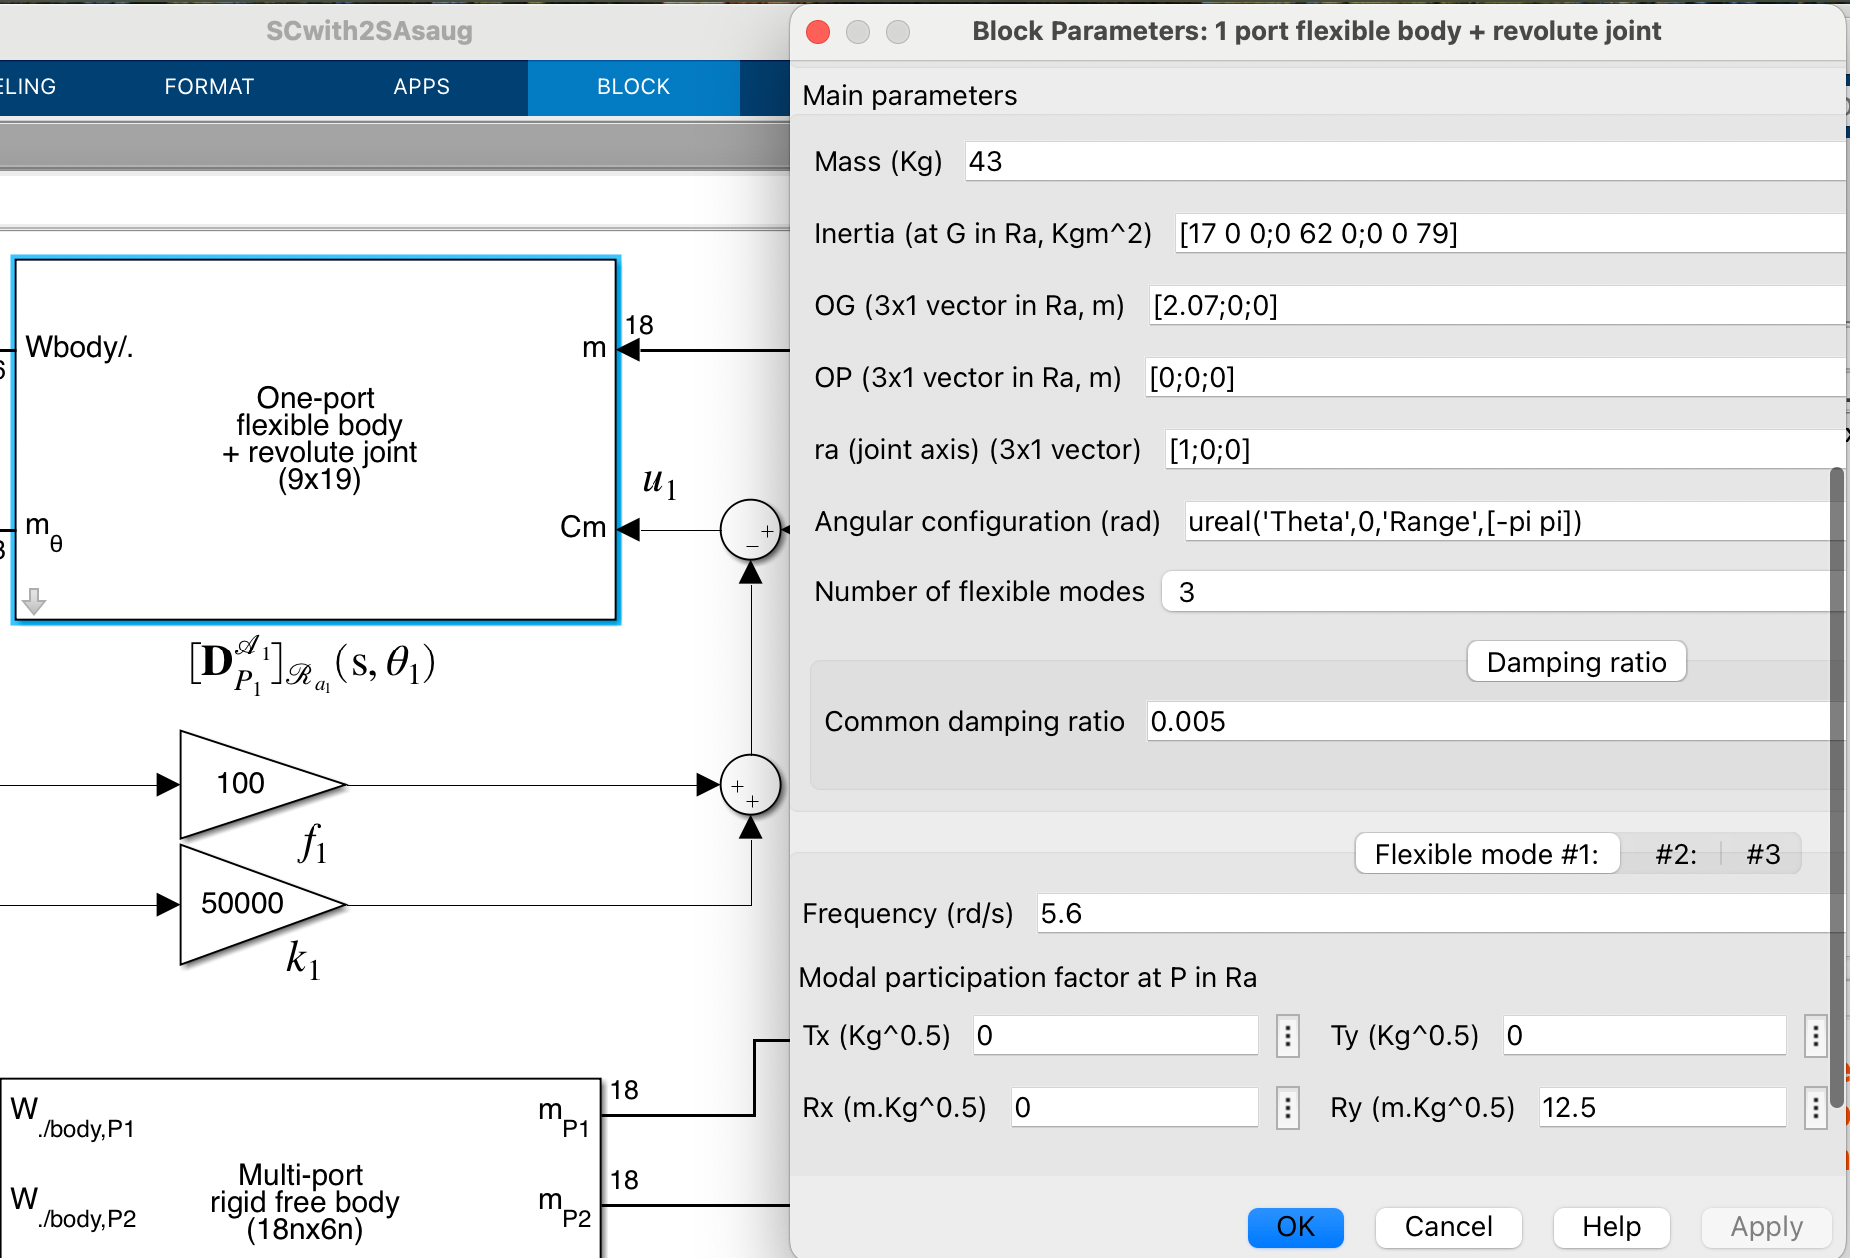

See also:

web Doconeportflexrevolute.html -new

### Data relative to the solar array $\mathcal A_2$:

Due to the symmetry this block is identical to the previous one except the revolute axis direction which is now: $[\mathbf r_{a_2}]_{\mathcal R_{a_2}}=[-1\quad 0\quad 0]^T$.

### Revolute joint driving mechanism:

The model $u_i=-k_i \delta\theta_i-f_i\dot{\delta\theta}_i+p_i$, $i=1,2$ can be directly included in the SIMULINK file by adding 2 integrators per revolute joint and the gains $k_i$ and $f_i$ for the in-joint stiffness and friction.

Numerical application: $k_1=k_2=50000\,Nm/rad$, $f_1=f_2=100\,Nms/rad$.

## 3. The whole  $6\times 8$ dynamic model

The whole model is then described by the following SIMULINK file `SCwith2SAs.slx`:

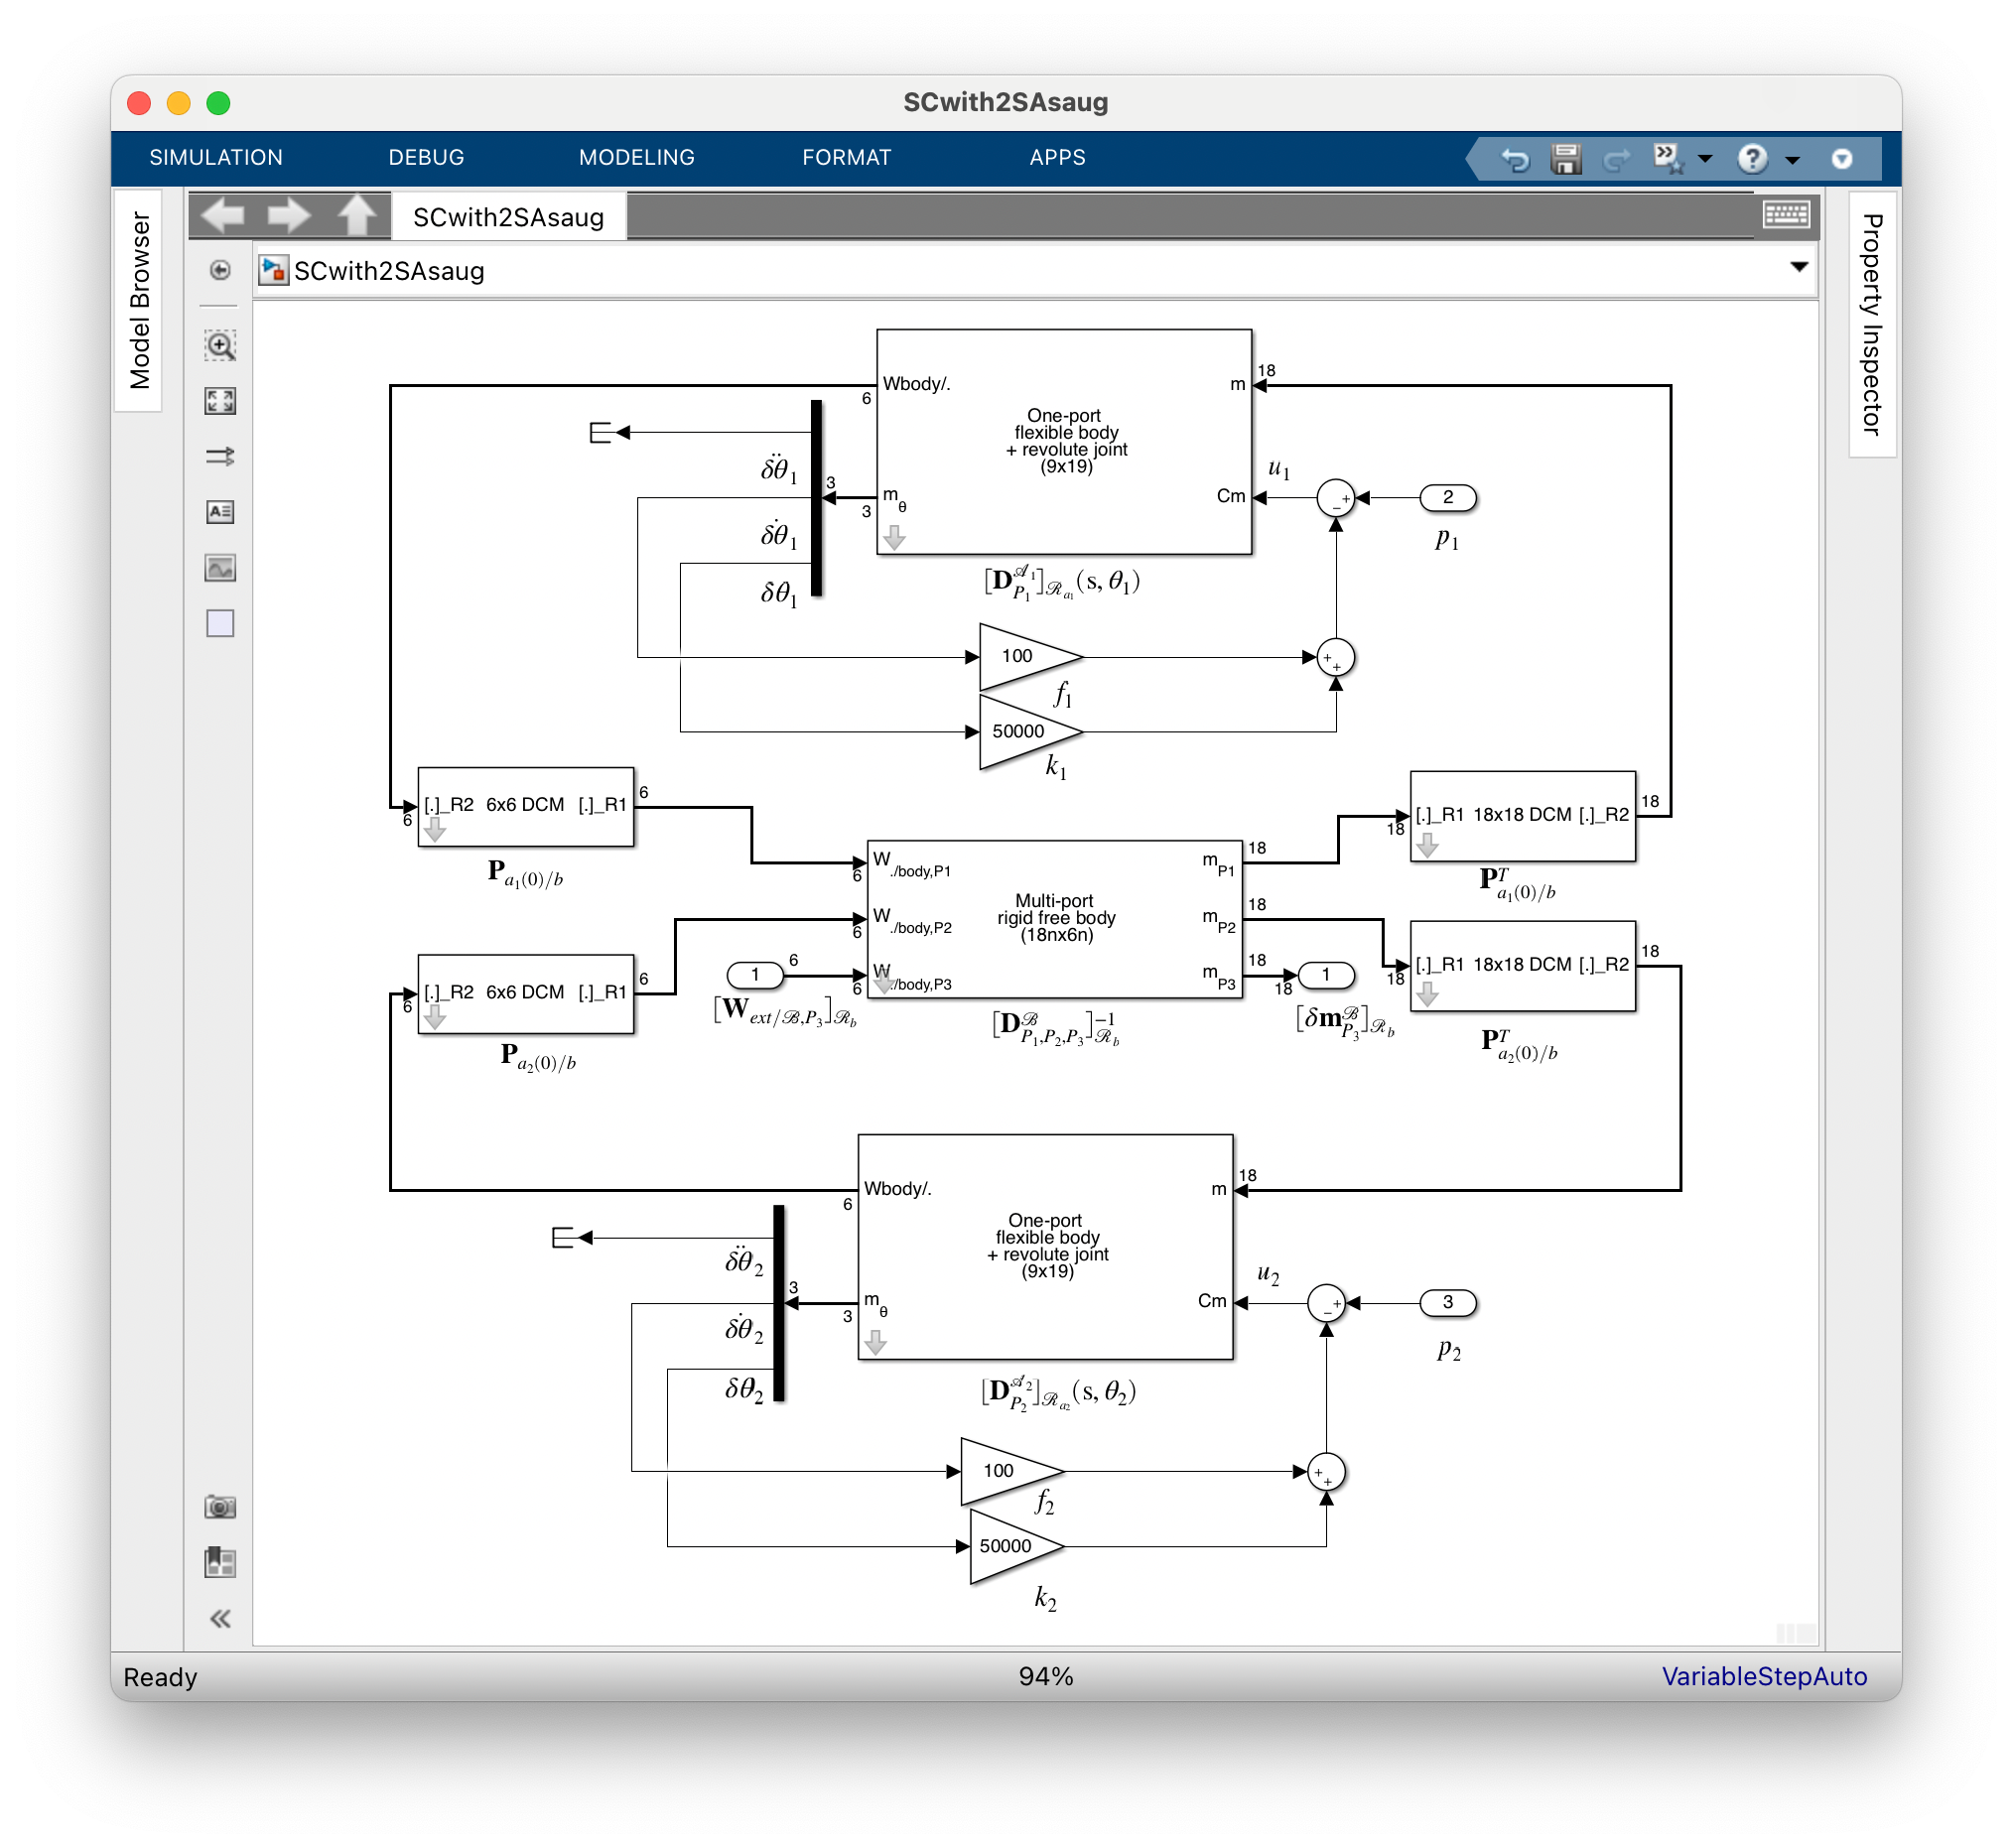

SCwith2SAsaug                      % the SIMULINK lile of the model
Gu=ulinearize('SCwith2SAsaug')

Gu =

  Uncertain continuous-time state-space model with 18 outputs, 8 inputs, 28 states.
  The model uncertainty consists of the following blocks:
    tan_Theta_div4: Uncertain real, nominal = 0, range = [-1,1], 32 occurrences

Type "Gu.NominalValue" to see the nominal value, "get(Gu)" to see all properties, and "Gu.Uncertainty" to interact with the uncertain elements.



One can check that the model have 8 inputs:

- the external wrench $[\mathbf W_{ext/\mathcal B,B}]_{\mathcal R_b}$ (6 components)

- $p_1$ the torque disturbance inside the revolute joint of $\mathcal A_1$,

- $p_2$ the torque disturbance inside the revolute joint of $\mathcal A_2$,

18 outputs:  the motion vector at point $B$ $[\delta\mathbf m^{\mathcal{SC}}_B]_{\mathcal R_b}$(18 components),

and 28 states: 8 modes (3 flexible modes + 1 revolute joint mode per appendage) + 6 rigid modes

This model depends on the uncertain parameter $\sigma_4=\tan\frac{\theta}{4}$ (`tan_Theta_div4`) with 32 occurences.

You can also check the correctness of the input geometry thanks to the SDTlib function view_SDTlib_model

help view_SDTlib_model

  This function reads a Simulink file containing the SDTlib model of a
  spacecraft, and creates a visual representation of this spacecraft.
  
  [] = view_SDTlib_model(filename, main_body, flag_frame, flag_port, flag_cog)
 
  Inputs:
  - filename = name of the Simulink file containing the SDTlib model,
  possibly with the name of the subsystem containing the SDTlib model.
  - main_body (optional) = name of the block corresponding to the "main body",
  typically the central rigid body. The reference frame of this body will
  be defined at point (0,0,0) and its reference frame will be aligned with
  the axes of the figure. By default (if '' is specified, or if not 
  specified), the function selects the rigid body with the highest mass.
  - flag_frame (optional): 1 to plot the reference frames, 0 (default) otherwise.
  - flag_port (opional) : 1 to plot the connection ports, 0 (default) otherwise.
  - flag_cog (optional) : 1 to plot the centers of gravity, 0 (default) ot

%figure
%view_SDTlib_model('SCwith2SAsaug','Multi port rigid body',1,1,1)

## 4. First analyses

It is now possible:

-  to compute the total $6\times 6$ mass/inertia of the spacecraft in the nominal configuration: $[\mathbf D_B^{\mathcal{SC}}]_{\mathcal R_b}(0,0)$:

inv(dcgain(Gu(1:6,1:6)))

ans = 	1.0e+03 *

    1.0860    0.0000   -0.0000   -0.0000    0.0000    0.0086
   -0.0000    1.0860    0.0000    0.0000   -0.0000    0.0043
    0.0000   -0.0000    1.0860   -0.0086   -0.0043    0.0000
   -0.0000   -0.0000   -0.0086    0.7679    0.0014    0.0020
   -0.0000    0.0000   -0.0043    0.0014    0.7662   -0.0010
    0.0086    0.0043   -0.0000    0.0020   -0.0010    0.1151


- plot the frequency-domain response (*Bode* magnitude) of the $3\times 3$ transfer between the force applied to the spacecraft and its position at $B$:

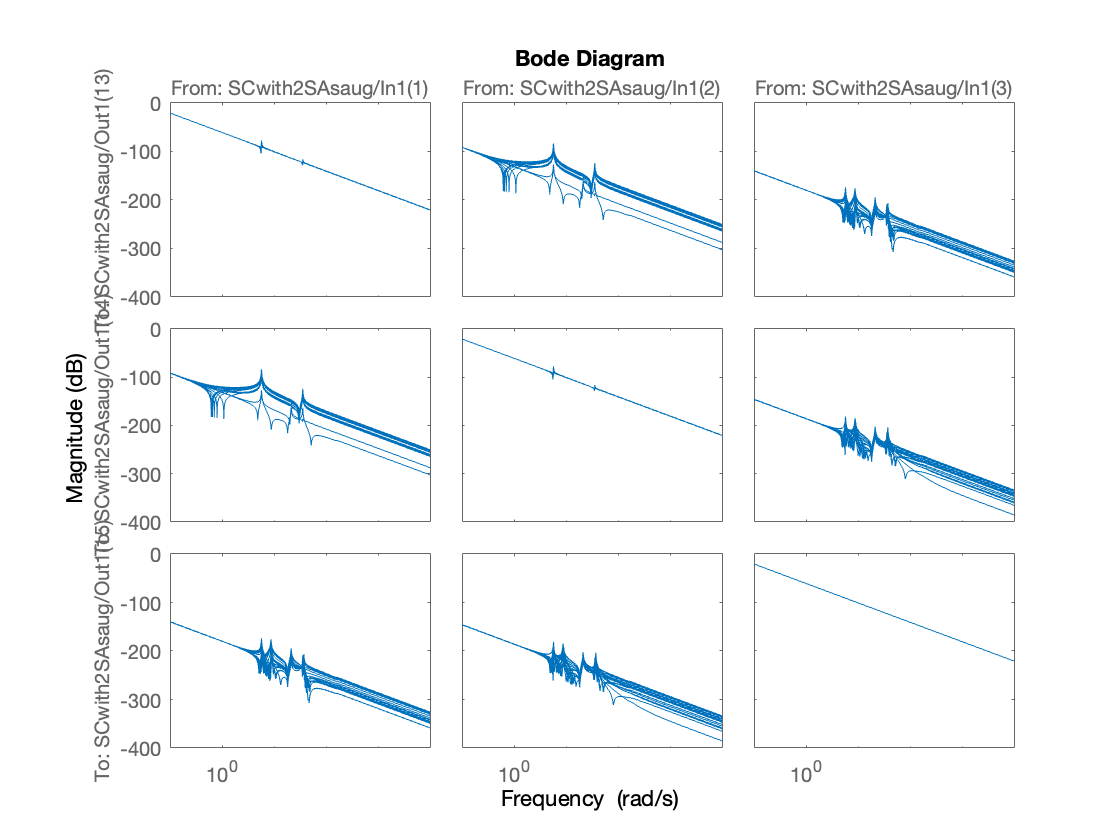

figure
bodemag(Gu(13:15,1:3))

- plot the frequency-domain response (Bode magnitude) of the $3\times 3$ transfer between the torque applied to the spacecraft at $B$ and its attitude:

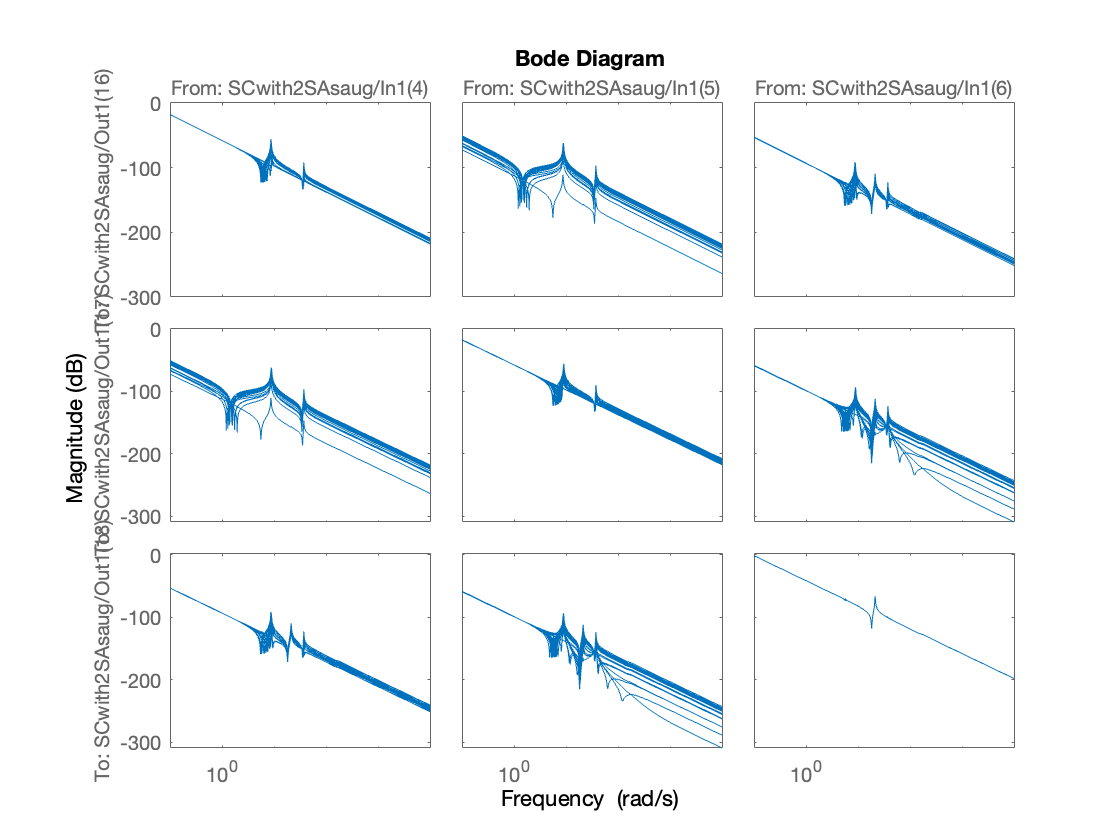

figure
bodemag(Gu(16:18,4:6))

- plot the frequency-domain response (Bode magitude) of the $3\times 1$ transfer between the disturbance $p_1$ and the attitude:

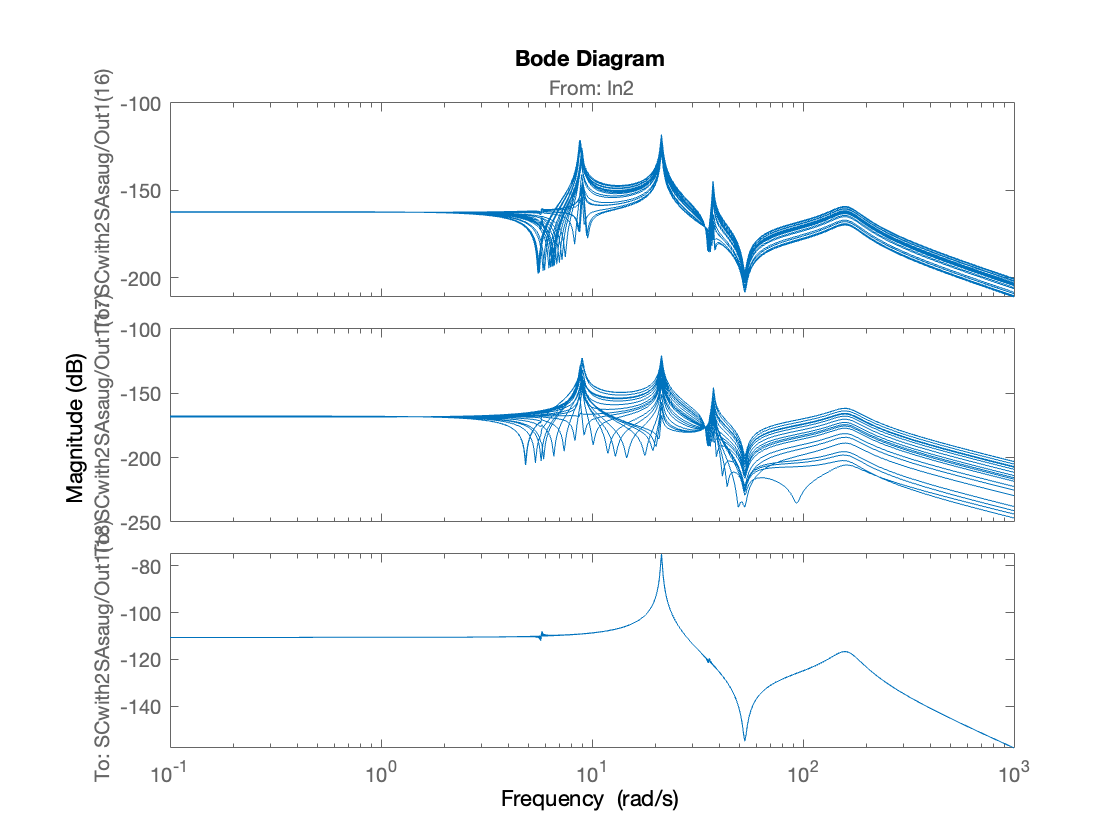

figure
bodemag(Gu(16:18,7),{1e-1,1e3})

Obviously, due to symmetry, the transfer from $p_1$ to the angular acceleration around $\mathbf z_b$ does not depend on the angular configuration $\theta$ of the solar pannel.

## 5. Remarks

- one can also dissociate the `Revolute joint` block (sub-library:` 6 dof mechanisms`) and the `1-port flexible body` (sub-library: `6 dof bodies`) . In such a case, the user have to provide the ouput shaft inertia of the revolute joint,

- for the solar array and with **full version** of the `SDTlib`, it is also possible to use the block `1 Port Nastran body `to avoid the declaration of the flexible mode data (frequency and modal participation factors). Then one have to specify the Nastran output file name `***.f06` (see tutorial 4 of the full version: [***a spacecraft with 2 symmetrical rotating solar arrays defined by a NASTRAN model***](matlab:open('../Tutorial4/tutorial4.html'))),

- it is also possible to use the `multi-port flexible plate `of the sub-library: `6 dof bodies `to model the solar array (see tutorial 8: [***a spacecraft with 2 symmetrical rotating solar array defined by a generic plate model***](matlab:open('../Tutorial8/tutorial8.html'))).

- In the various blocks of the **6 dof bodies** sub-library, the dialog box requires to fill for a given body $\mathcal C$: (i) the mass $m^{\mathcal C}$, (ii) the $3\times 3$ inertia tensor $[\mathbf J^\mathcal C
_G]_{\mathcal R_c}$ of the body $\mathcal C$ at its center of mass $G$ and (iii) the vector $[\overrightarrow{OG}]_{\mathcal R_c}$from a reference point $O$ to the center of mass $G$. In some application, the only data available is the $6\times 6$ total mass/inertia matrix $[\mathbf D^{\mathcal C}_O]_{\mathcal R_c}$(also called direct dynamic model) at a reference point $O$. Then, one can apply the dynamic model transport property:  $\mathbf{D}^{\mathcal{C}}_O=\mathbf\tau_{GO}^T\, \mathbf{D}^{\mathcal{C}}_G\,\mathbf\tau_{GO}=\left[\begin{array}{cc}m^{\mathcal{C}}\mathbf{1}_3 & m^{\mathcal{C}}\,(^*\overrightarrow{GO})\\ -m^{\mathcal{C}}\,(^*\overrightarrow{GO}) & \underbrace{\mathbf{J}^{\mathcal{C}}_G -m^{\mathcal{C}}\,(^*\overrightarrow{GO})^2}_{\mathbf{J}^{\mathcal{C}}_O}\end{array}\right]$ which is valid in any frame to recover the required data:  $m^{\mathcal C}$, $\overrightarrow{OG}$, $\mathbf J^\mathcal C_G=\mathbf J^\mathcal C_O+m^\mathcal C\,(^*\overrightarrow{OG})^$ where $(^*\overrightarrow{OG})$  is the antisymmetric matrix associated to the vector $\overrightarrow{OG}$. That can be easily implemented thanks to the function `antisym.m `as illustrated in the following example.

D_CatO=[50 0 0 0 50 0;0 50 0 -50 0 100;0 0 50 0 -100 0;...
        0 -50 0 67 0 -100;50 0 -100 0 312 0;0 100 0 -100 0 280]

D_CatO =     50     0     0     0    50     0
     0    50     0   -50     0   100
     0     0    50     0  -100     0
     0   -50     0    67     0  -100
    50     0  -100     0   312     0
     0   100     0  -100     0   280


m_C=D_CatO(1,1)

m_C = 50

OG=[D_CatO(2,6);-D_CatO(1,6);D_CatO(1,5)]/m_C

OG =      2
     0
     1


J_CatG=D_CatO(4:6,4:6)+m_C*antisym(OG)^2

J_CatG =     17     0     0
     0    62     0
     0     0    80
